# Ejercicio 3.02 

Usa la Robotics System Toolbox v2.2

Transformación homogénea en un prisma.

T0=[1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];

% Dibujamos el cubo que contiene la cuña
a=6; b=4; c=1.5;
voxel([0 0 0],[-a b c],'r',0.1);
grid on		% Se establece una rejilla
view(115,15)	% Se establece el punto de vista
axis equal

% Representación del frame 0:
pframe(T0,'c',1.2);

% el frame 1, en color azul:
T1=trvec2tform([0 b c]) * axang2tform([0 0 1 pi]) * axang2tform([1 0 0 -pi/2])*T0

T1 =    -1.0000   -0.0000   -0.0000         0
    0.0000   -0.0000   -1.0000    4.0000
         0   -1.0000    0.0000    1.5000
         0         0         0    1.0000


pframe(T1,'b',1.2);

% el frame 1, calculado en ejes moviles (postmultiplicar):
T1= T0 * axang2tform([1 0 0 -pi/2]) * axang2tform([0 1 0 -pi])*trvec2tform([0 -c -b])

T1 =    -1.0000         0   -0.0000    0.0000
    0.0000    0.0000   -1.0000    4.0000
    0.0000   -1.0000   -0.0000    1.5000
         0         0         0    1.0000


pframe(T1,'g',.8);

% el frame 2 desde el 1, en rojo:
T2=trvec2tform([c-a b b]) * axang2tform([0 0 1 pi/2]) * axang2tform([1 0 0 -pi/2])*T1

T2 =    -0.0000    1.0000    0.0000   -6.0000
   -1.0000   -0.0000   -0.0000    4.0000
   -0.0000   -0.0000    1.0000         0
         0         0         0    1.0000


pframe(T2,'r',1.2);

% el frame 2 desde el 0, debe ser igual:
T2=trvec2tform([-a b 0]) * axang2tform([0 0 1 -pi/2]) *T0

T2 =     0.0000    1.0000         0   -6.0000
   -1.0000    0.0000         0    4.0000
         0         0    1.0000         0
         0         0         0    1.0000


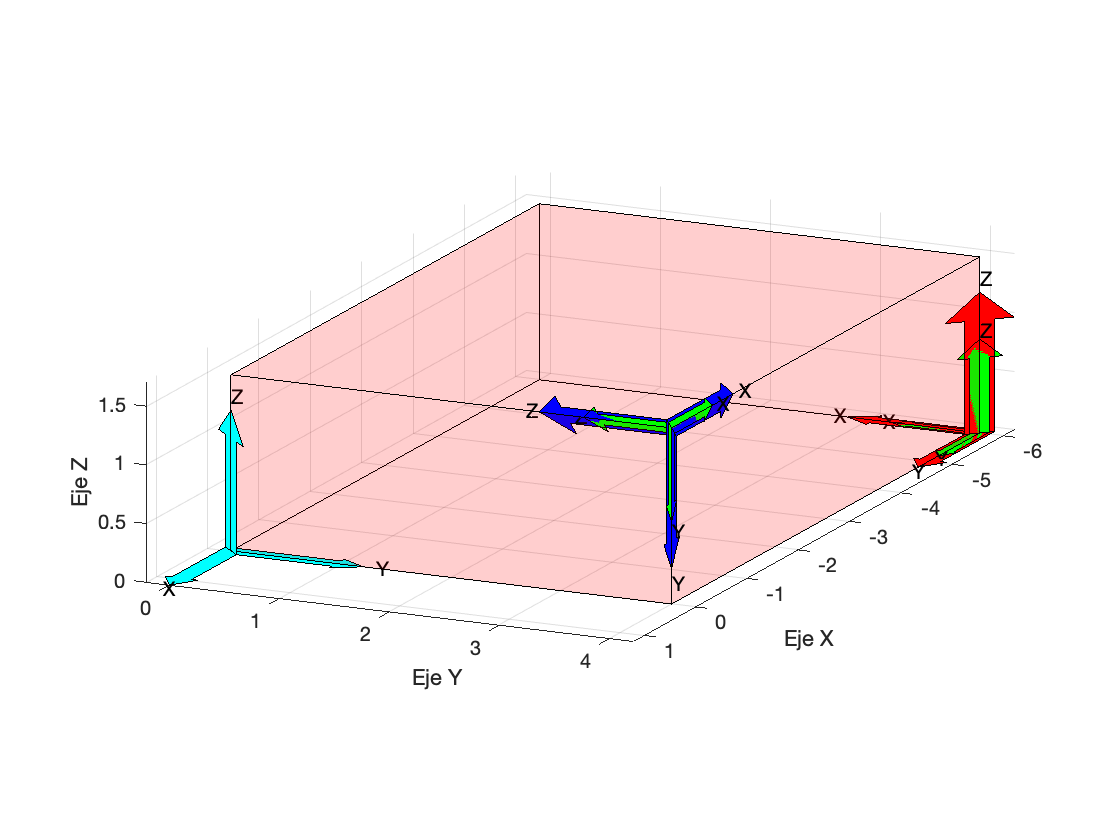

pframe(T2,'g',.8);